# **Obtener los datos del archivo .csv**

data = readmatrix("../Data/150_120_CQRobot.csv");

t = data(:,1); %tiempo
u = data(:,2); %señal de entrada
y = data(:,3); %señal de salida

Ts = 0.0370;

# **Gráfica de la salida del sistema**

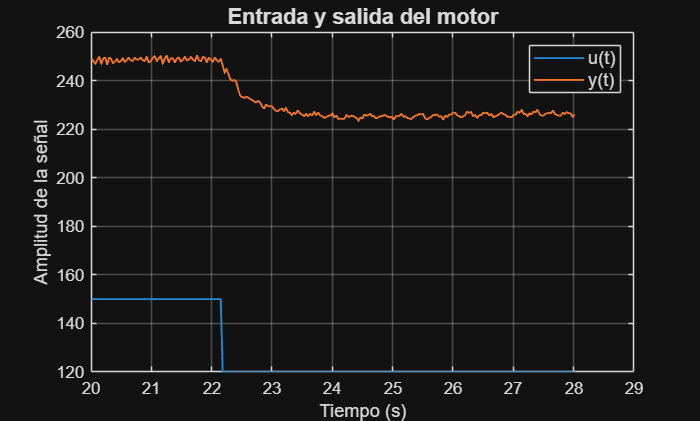

figure(1);
plot(t,u,t,y,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('u(t)', 'y(t)','FontSize',11);
title('Entrada y salida del motor', 'FontSize',13);
grid on;

# **Eliminar el DC Offset**

porcentaje_inicial = 0.10; % Se toma un aproximado de qué porcentaje de la respuesta 
num_puntos = length(y);
puntos_iniciales = round(porcentaje_inicial * num_puntos);
dc_offset_u = mean(u(1:puntos_iniciales));
dc_offset_y = mean(y(1:puntos_iniciales));

u_sindc = u - dc_offset_u;
y_sindc = y - dc_offset_y;

# **Gráfica de la salida sin el DC Offset**

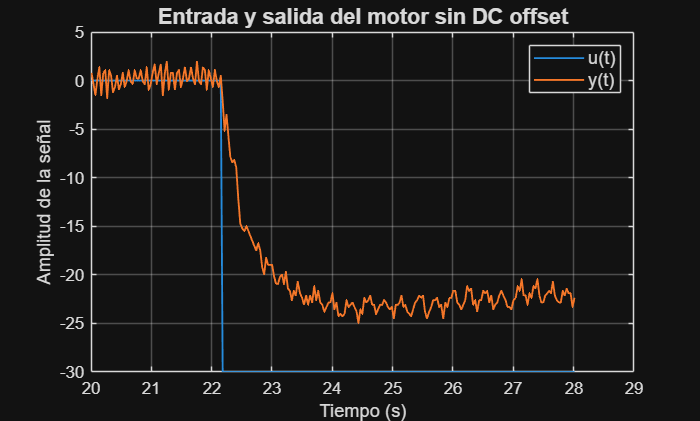

figure(2);
plot(t, u_sindc, t, y_sindc, 'LineWidth',1.1);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# **Abrir el System Identification Toolbox**

systemIdentification();

Se puede cargar el valor de la planta ya calculada con un 90.84% de precisión dándole click al modelo_primer_orden.mat

# Gráfica con del modelo de Toolbox

t1 = (20:0.0370:29)'

t1 =            20
       20.037
       20.074
       20.111
       20.148
       20.185
       20.222
       20.259
       20.296
       20.333
        20.37
       20.407
       20.444
       20.481
       20.518


%Planta obtenida por toolbox
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.


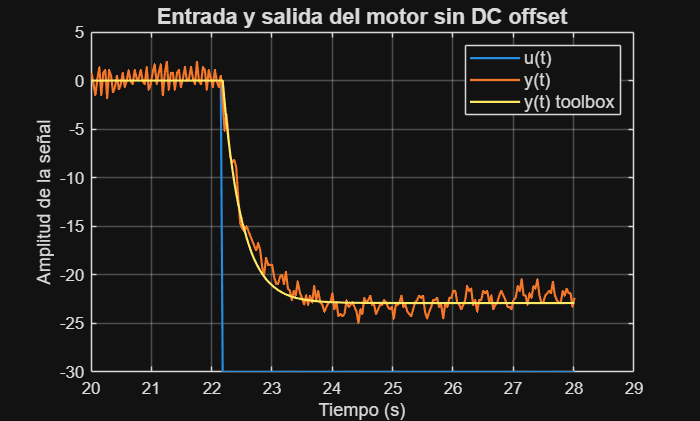

Kp = 0.7634;
T = 0.3649;
P = Kp/(T*s+1);

y_sim = lsim(P, u_sindc, t1);

figure(3);
plot(t, u_sindc, t, y_sindc, t, y_sim, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) toolbox', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Método de mínimos cuadrados

Y = y_sindc(3:end);
X = [y_sindc(2:end-1) y_sindc(1:end-2) u_sindc(2:end-1) u_sindc(1:end-2)];

cita = (X' * X) \ (X' * Y);

cita = round(cita,4); % se redondea el cita a 4 decimales
z = tf('z');
Hz = tf([cita(3) cita(4)], [1 -cita(1) -cita(2)], Ts); % se crea la función de transferencia
format shortG
Hz


Hz =
 
     0.1437 z - 0.0514
  -----------------------
  z^2 - 0.5008 z - 0.3763
 
Sample time: 0.037 seconds
Discrete-time transfer function.


# Gráfica con el método de mínimos cuadrados

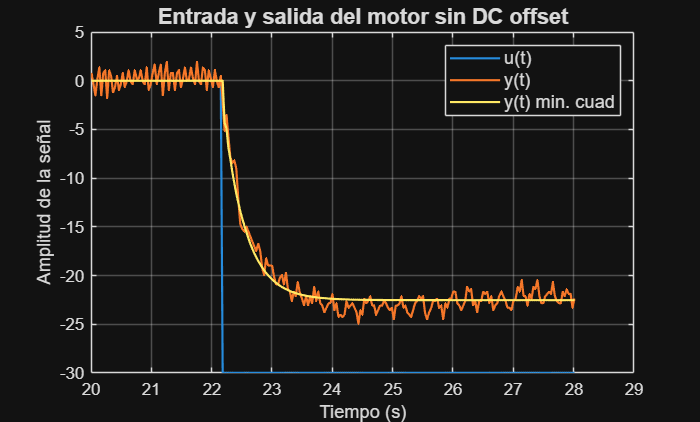

y_sim1 = lsim (Hz, u_sindc);

figure(4);
plot(t, u_sindc, t, y_sindc, t, y_sim1, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) min. cuad', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# ** Datos necesarios para el método de Alfaro**

porcentaje_final = 0.10; % Se toma un aproximado de donde la respuesta tiene su valor final
num_puntos = length(y);
puntos_final = round(porcentaje_final * num_puntos);
y_final = y_sindc(end-puntos_final+1:end);
promedio_yfinal = mean(y_final);

% Calcular y_inicial 
puntos_iniciales = round(0.10 * num_puntos);
y_inicial = mean(y_sindc(1:puntos_iniciales));

% Encontrar cambio_esc
cambio_esc = find(u_sindc < 0, 1);

deltau = u(1) - u(cambio_esc);

deltay = y_inicial - promedio_yfinal;

deltay25 = y_inicial - 0.25 * deltay;
deltay50 = y_inicial - 0.5 * deltay;
deltay75 = y_inicial - 0.75 * deltay;

% Se encuentran las posiciones en el vector tiempo de cada porcentaje de delta y
% Para t25
todos_t25 = find(y_sindc(cambio_esc:end) <= deltay25);
pos_t25 = todos_t25(min(1, end)) + cambio_esc - 1;

% Para t50
todos_t50 = find(y_sindc(cambio_esc:end) <= deltay50);
pos_t50 = todos_t50(min(1, end)) + cambio_esc - 1;

% Para t75
todos_t75 = find(y_sindc(cambio_esc:end) <= deltay75);
pos_t75 = todos_t75(min(1, end)) + cambio_esc - 1;

% Se obtiene los tiempos en donde ocurren los porcentajes y el cambio escalon
t25_tot = t(pos_t25);
t50_tot = t(pos_t50);
t75_tot = t(pos_t75);
tcambio = t(cambio_esc);

% Se resta el tiempo antes de hacer el cambio escalón
t25 = t25_tot - tcambio;
t50 = t50_tot - tcambio;
t75 = t75_tot - tcambio;

# Método de PDMTM Alfaro (método de 2 puntos)

a = 0.5776

a =        0.5776


b = 1.5552

b =        1.5552


K = deltay / deltau;
Talf = a*(t75 - t25);
%No se calcula L ya que la planta no tiene tiempo muerto

# Gráfica con el método de Alfaro PDMTM

s = tf('s');
P1 = K / (Talf*s + 1)^2


P1 =
 
            0.7339
  --------------------------
  0.06116 s^2 + 0.4946 s + 1
 
Continuous-time transfer function.


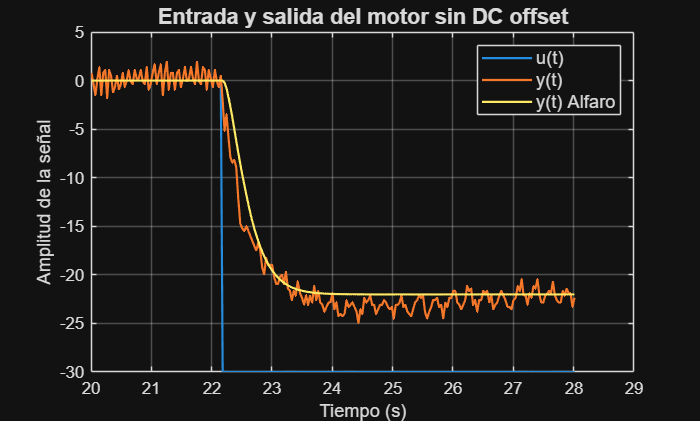

y_sim2 = lsim (P1, u_sindc, t1);
figure(5);

plot(t, u_sindc, t, y_sindc, t, y_sim2, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)', 'y(t) Alfaro','FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Cálculo de lo necesario para Ho

deltay35 = y_inicial - 0.35 * deltay;
deltay85 = y_inicial - 0.85 * deltay;

% Se encuentran las posiciones en el vector tiempo de cada porcentaje de delta y
% Para t35
todos_t35 = find(y_sindc(cambio_esc:end) <= deltay35);
pos_t35 = todos_t35(min(1, end)) + cambio_esc - 1;

% Para t85
todos_t85 = find(y_sindc(cambio_esc:end) <= deltay85);
pos_t85 = todos_t85(min(1, end)) + cambio_esc - 1;

% Se obtiene los tiempos en donde ocurren los porcentajes y el cambio escalon
t35_tot = t(pos_t35);
t85_tot = t(pos_t85);

% Se resta el tiempo antes de hacer el cambio escalón
t35 = t35_tot - tcambio;
t85 = t85_tot - tcambio;

# Método de PDMTM Ho (método de 2 puntos)

aho = 0.463

aho =         0.463


K = deltay / deltau;
Tho = aho*(t85 - t35);

%No se calcula L ya que la planta no tiene tiempo muerto
P2 = K / (Tho*s + 1)^2


P2 =
 
            0.7339
  --------------------------
  0.05966 s^2 + 0.4885 s + 1
 
Continuous-time transfer function.


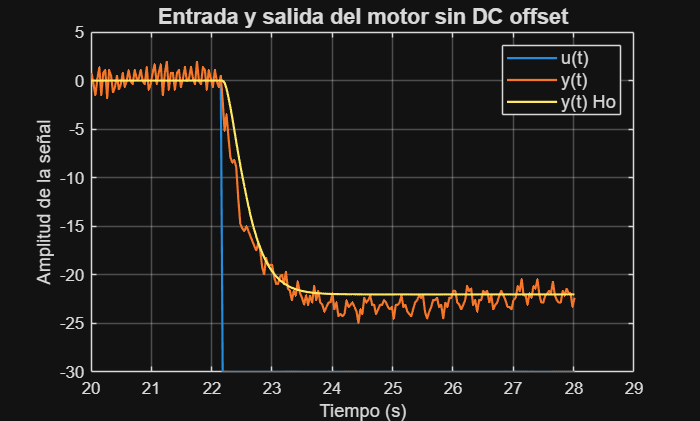

y_sim3 = lsim (P2, u_sindc, t1);

figure(6);
plot(t, u_sindc, t, y_sindc, t, y_sim3, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) Ho', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Método de alfaro 3 puntos

a3 = (-0.6240*t25 + 0.9866*t50 - 0.3626*t75)/(0.3533*t25 - 0.7036*t50 + 0.3503*t75);
T3 = (t75 - t25) / (0.9866+0.7036*a)

T3 =       0.30736


% No se calcula L ya que no tiene tiempo muerto

P3 = K/((T3*s+1)*(a*T3*s+1))


P3 =
 
            0.7339
  --------------------------
  0.05457 s^2 + 0.4849 s + 1
 
Continuous-time transfer function.


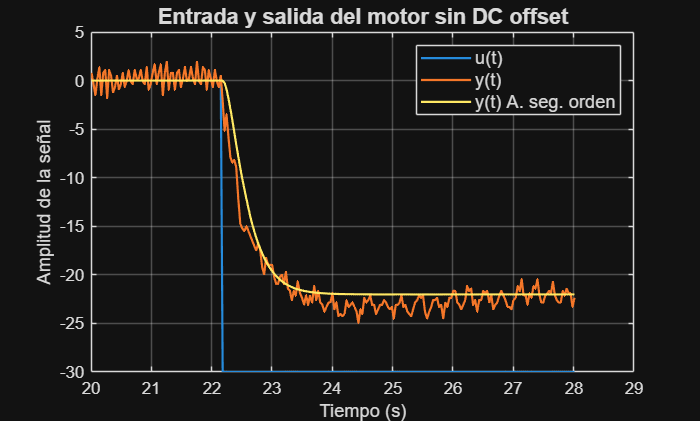

y_sim4 = lsim (P3, u_sindc, t1);

figure(7);
plot(t, u_sindc, t, y_sindc, t, y_sim4, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) A. seg. orden', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Comparación de las gráficas

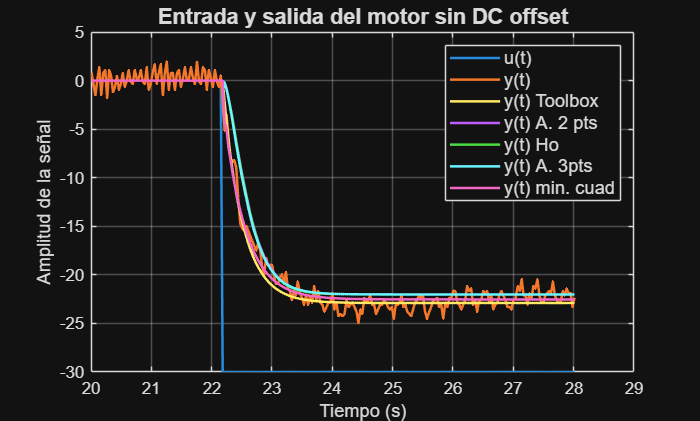

figure(8);
plot(t, u_sindc, t, y_sindc, t, y_sim, t, y_sim2, t, y_sim3, t, y_sim4,t, y_sim1,'LineWidth',1.5);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) Toolbox','y(t) A. 2 pts', 'y(t) Ho', 'y(t) A. 3pts', 'y(t) min. cuad','FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Cálculos para elección de modelo de planta

%% Planta obtenida a través de toolbox
e_tbx = y_sindc - y_sim; % error de la planta de toolbox

IAE_tbx = sum(abs(e_tbx)) * Ts; % índice integral de error absoluto de la planta toolbox
ISE_tbx = sum(e_tbx.^2) * Ts; % índice de error cuadrático de la planta toolbox
ajuste_tbx = 100 * (1 - norm(e_tbx)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta toolbox

%% Planta obtenida a través de Alfaro 2 puntos
e_alfdos = y_sindc - y_sim2; % error de la planta de Alfaro 2 puntos

IAE_alfdos = sum(abs(e_alfdos)) * Ts; % índice integral de error absoluto de la planta de Alfaro 2 puntos
ISE_alfdos = sum(e_alfdos.^2) * Ts; % índice de error cuadrático de la planta Alfaro 2 puntos
ajuste_alfdos = 100 * (1 - norm(e_alfdos)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta de Alfaro 2 puntos


%% Planta obtenida a través de Ho 2 puntos
e_hodos = y_sindc - y_sim3; % error de la planta de Ho 2 puntos

IAE_hodos = sum(abs(e_hodos)) * Ts; % índice integral de error absoluto de la planta de Ho 2 puntos
ISE_hodos = sum(e_hodos.^2) * Ts; % índice de error cuadrático de la planta Ho 2 puntos
ajuste_hodos = 100 * (1 - norm(e_hodos)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta de Ho 2 puntos

%% Planta obtenida a través de Alfaro 3 puntos
e_alftres = y_sindc - y_sim4; % error de la planta de Alfaro 3 puntos

IAE_alftres = sum(abs(e_alftres)) * Ts; % índice integral de error absoluto de la planta de Alfaro 3 puntos
ISE_alftres = sum(e_alftres.^2) * Ts; % índice de error cuadrático de la planta Alfaro 3 puntos
ajuste_alftres = 100 * (1 - norm(e_alftres)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta de Alfaro 3 puntos

# Datos relevantes y elección de planta

IAE_vec = [IAE_tbx, IAE_alfdos, IAE_hodos, IAE_alftres];
ISE_vec = [ISE_tbx, ISE_alfdos, ISE_hodos, ISE_alftres];
ajuste_vec = [ajuste_tbx, ajuste_alfdos, ajuste_hodos, ajuste_alftres];
nombres = {'Toolbox', 'Alfaro 2p', 'Ho 2p', 'Alfaro 3p'};

[~, mejor_IAE] = min(IAE_vec);
[~, mejor_ISE] = min(ISE_vec);
[~, mejor_ajuste] = max(ajuste_vec);

%% Resultados
fprintf('Mejor IAE: %s (%.4f)\n', nombres{mejor_IAE}, IAE_vec(mejor_IAE));

Mejor IAE: Toolbox (7.2772)


fprintf('Mejor ISE: %s (%.4f)\n', nombres{mejor_ISE}, ISE_vec(mejor_ISE));

Mejor ISE: Toolbox (9.1954)


fprintf('Mejor Ajuste: %s (%.4f%%)\n', nombres{mejor_ajuste}, ajuste_vec(mejor_ajuste));

Mejor Ajuste: Toolbox (90.0214%)


# Cálculo controlador PI con Síntesis Analítica para P1D

%Cálculo tauc de acuerdo Ms = 1.0
tauc = 3.8 * T;
%Cálculo parámetros del controlador
ksn = (2- tauc)/(tauc * Kp);
tisn = tauc * T * (2 - tauc);

%Controlador C2 con método síntesis analítica
C1 = ksn *(1 + 1/(tisn*s))


C1 =
 
  0.1798 s + 0.5795
  -----------------
      0.3104 s
 
Continuous-time transfer function.


# Gráfica salida con controlador por Síntesis analítica

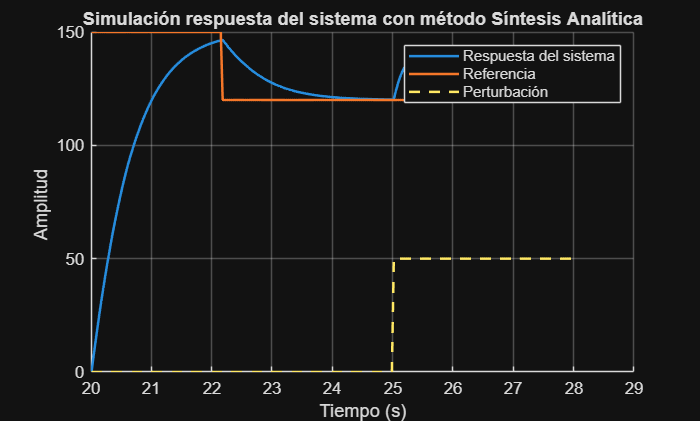

Myrsn = ( C1 * P ) /(1+ C1 * P ) ;
Mydsn = minreal ( P /(1+ C1 * P ) ) ;
Mursn = C1/(1+C1*P);
Mudsn = (-C1*P)/(1+C1*P);

r = u;

d = 0; %perturbacion
d ( t >= 25) = 50;
yrsn = lsim ( Myrsn , r , t1 ) ;
ydsn = lsim ( Mydsn , d , t1 ) ;
ysn = yrsn + ydsn;


ursn = lsim (Mursn, r, t1);
udsn = lsim(Mudsn, d, t1);
usn = ursn + udsn;

%% indices de la simulacion
indices = t1 >= 25;
r_segmentsn = r(indices); % Valores de r donde t >= 25  
y_segmentsn = ysn(indices); % Valores de y donde t >= 25

%calcular el error para la perturbación
e_lsn = r_segmentsn - y_segmentsn;

% Calcular los índices
Emaxlsn = max(abs(e_lsn));
yfdlsn = y_segmentsn(end);
rfdlsn = r_segmentsn(end);
epdlsn = rfdlsn - yfdlsn;       
IAE_lsn = sum(abs(e_lsn)) * Ts;
TVudsn = sum(abs(diff(usn))); % esfuerzo de control

figure (9);
title ('Simulación respuesta del sistema con método Síntesis Analítica') ;
xlabel ('Tiempo (s)') ;
ylabel ('Amplitud ') ;
hold on ;
grid ('on') ;
plot (t , ysn, 'LineWidth', 1.5);
hold on;
plot(t, r, 'LineWidth', 1.5);
hold on ;
plot (t, d, '--', 'LineWidth', 1.5);
legend('Respuesta del sistema', 'Referencia', 'Perturbación');

# Gráfica prueba experimental del controlador por Síntesis Analítica

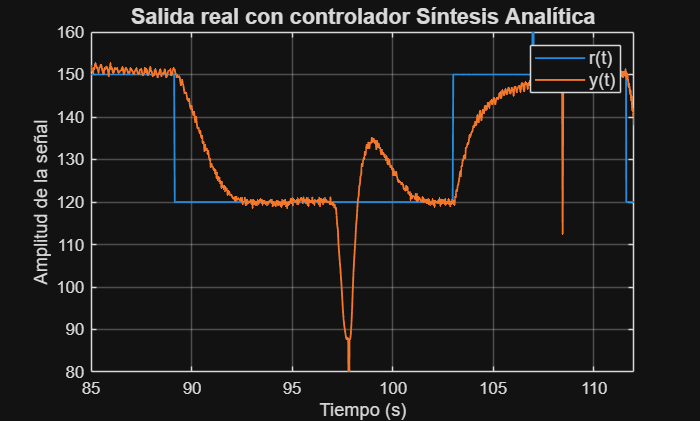

datasn = readmatrix("../Data/datos_motor-3-3_sintesis_analitica.csv");
tsn = datasn(:,1); %tiempo
rsn = datasn(:,2) - 40; %señal de referencia
usn = datasn(:,3) - 40; %señal de control
ysn = datasn(:,4) - 40;

figure(10);
plot(tsn,rsn,tsn,ysn,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('r(t)','y(t)','FontSize',11);
title('Salida real con controlador Síntesis Analítica', 'FontSize',13);
ylim ([80 160])
xlim ([85 112])
grid on;

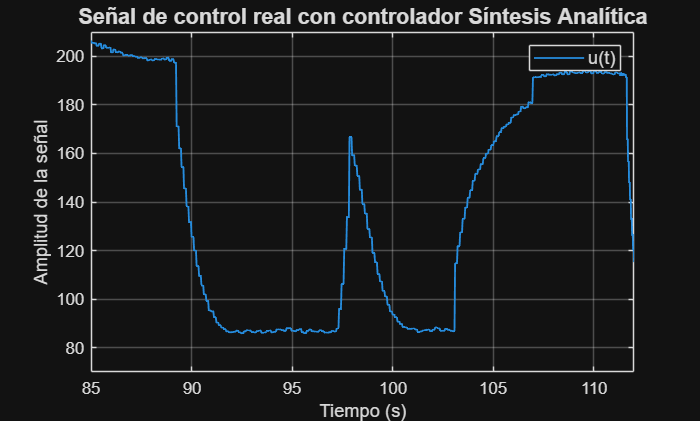

figure(11);
plot(tsn,usn,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('u(t)','FontSize',11);
title('Señal de control real con controlador Síntesis Analítica', 'FontSize',13);
ylim ([70 210])
xlim ([85 112])
grid on;

# Controlador con el método Lambda

lambda = 0.6*T; % se elige luego de un barrido de valores de lambda y este es el más idóneo
Kclbd = T/(Kp*lambda);
Tilbd = T;

C2 = Kclbd *(1 + 1/(Tilbd*s))


C2 =
 
  0.7967 s + 2.183
  ----------------
      0.3649 s
 
Continuous-time transfer function.


# Gráfica del controlador con el método Lambda

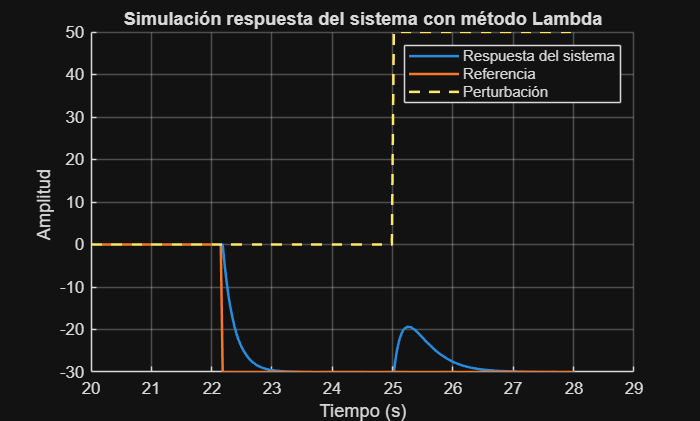

Myr1 = ( C2 * P ) /(1+ C2 * P ) ;
Myd1 = minreal ( P /(1+ C2 * P ) ) ;

r = u_sindc;

d = 0; %perturbacion
d ( t >= 25) = 50;
yr1 = lsim ( Myr1 , r , t1 ) ;
yd1 = lsim ( Myd1 , d , t1 ) ;
y1 = yr1 + yd1;

figure (12);
title ('Simulación respuesta del sistema con método Lambda') ;
xlabel ('Tiempo (s)') ;
ylabel ('Amplitud ') ;
hold on ;
grid ('on') ;
plot (t , y1, 'LineWidth', 1.5);
hold on;
plot(t, r, 'LineWidth', 1.5);
hold on ;
plot (t, d, '--', 'LineWidth', 1.5);
legend('Respuesta del sistema', 'Referencia', 'Perturbación');

# Gráfica prueba experimental con el controlador por el método Lambda

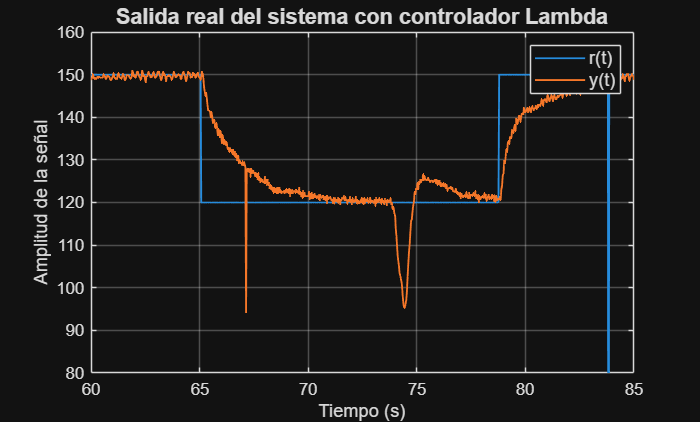

datalbd = readmatrix("../Data/datos_motor-3-3_lambda.csv");
tlbd = datalbd(:,1); %tiempo
rlbd = datalbd(:,2) - 40; %señal de referencia
ulbd = datalbd(:,3) - 40; %señal de control
ylbd = datalbd(:,4) - 40;

figure(13);
plot(tlbd,rlbd,tlbd,ylbd,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('r(t)','y(t)','FontSize',11);
title('Salida real del sistema con controlador Lambda', 'FontSize',13);
ylim ([80 160])
xlim ([60 85])
grid on;

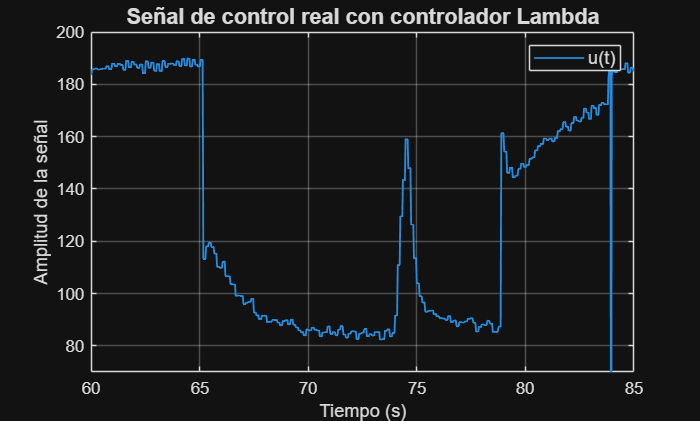

figure(14);
plot(tlbd,ulbd,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('u(t)','FontSize',11);
title('Señal de control real con controlador Lambda', 'FontSize',13);
ylim ([70 200])
xlim ([60 85])
grid on;

# Controlador con el método H-infinite

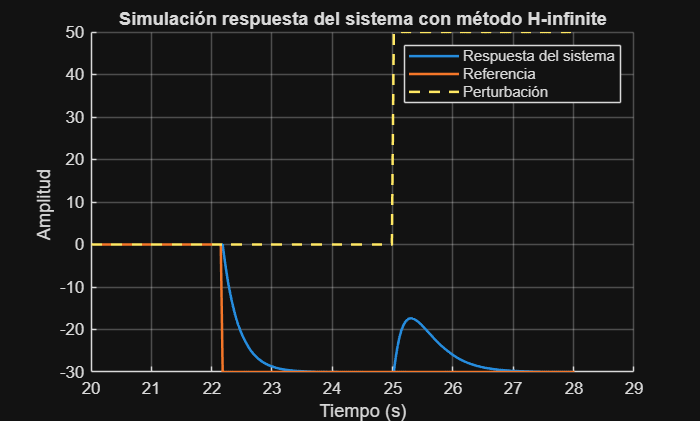

lambdah = 0.9*T;
h= 0; % porque no hay tiempo muerto

Kch = (1/Kp)*(T/(lambdah+h))*((h+2*lambdah-(lambdah^2/T))/(h+lambdah));
Tih = (T*(h+2*lambdah)-lambdah^2)/(T + h);

C3 = Kch *(1 + 1/(Tih*s));

Myr2 = ( C3 * P ) /(1+ C3 * P ) ;
Myd2 = minreal ( P /(1+ C3 * P ) ) ;

r = u_sindc;

d = 0; %perturbacion
d ( t >= 25) = 50;
yr2 = lsim ( Myr2 , r , t1 ) ;
yd2 = lsim ( Myd2 , d , t1 ) ;
y2 = yr2 + yd2;

figure (15);
title ('Simulación respuesta del sistema con método H-infinite') ;
xlabel ('Tiempo (s)') ;
ylabel ('Amplitud ') ;
hold on ;
grid ('on') ;
plot (t , y2, 'LineWidth', 1.5);
hold on;
plot(t, r, 'LineWidth', 1.5);
hold on ;
plot (t, d, '--', 'LineWidth', 1.5);
legend('Respuesta del sistema', 'Referencia', 'Perturbación');

# Gráfica experimental con el controlador H-infinite

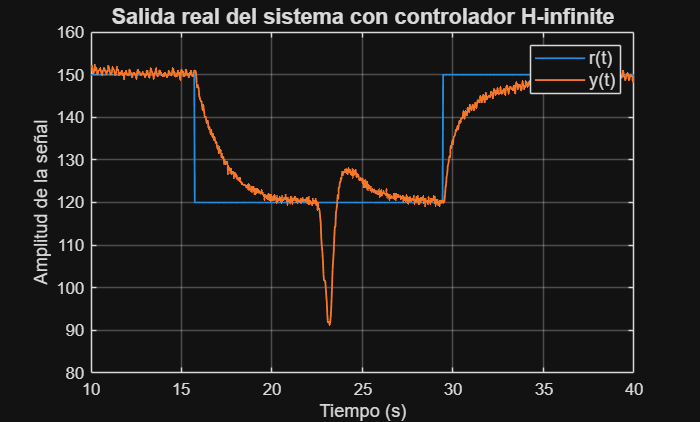

datah = readmatrix("../Data/datos_motor_3-3_hinfinite.csv");
th = datah(:,1); %tiempo
rh = datah(:,2) - 40; %señal de referencia
uh = datah(:,3) - 40; %señal de control
yh = datah(:,4) - 40;

figure(16);
plot(th,rh,th,yh,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('r(t)','y(t)','FontSize',11);
title('Salida real del sistema con controlador H-infinite', 'FontSize',13);
ylim ([80 160])
xlim ([10 40])
grid on;

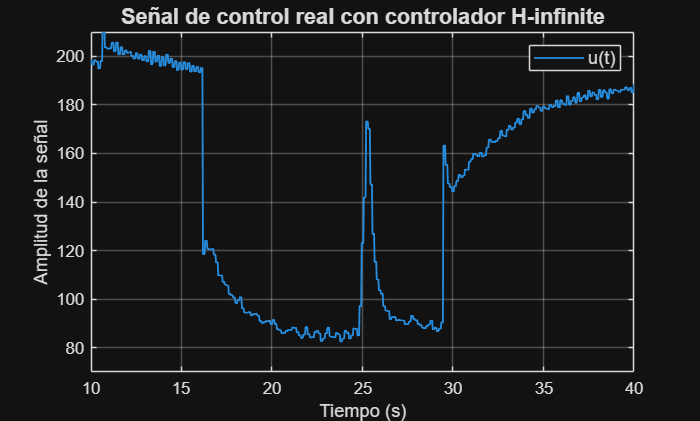


figure(17);
plot(tlbd,ulbd,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('u(t)','FontSize',11);
title('Señal de control real con controlador H-infinite', 'FontSize',13);
ylim ([70 210])
xlim ([10 40])
grid on;